# Final Project

## Paul Keene, Erica Lin

Dataset: Steinmetz, Zatka-Haas, Carandini & Harris 2019

## Setup

%set project directory (will need to change on different machine)
projDir = pwd;

%get session IDs and number
[sessionNames,nsesh] = getSessionNames(projDir);

%load the data from the raw files
[beh,eye] = loadData(sessionNames,nsesh,projDir);
load('sorted_data/neural/spikes.mat'); %we used the preprocessing scripts indexClusters and selectClusters to make this


% load paths for functions
visualization_path = [pwd,'/visualize']; 
addpath(visualization_path);
analysis_path = [pwd,'/analysis']; 
addpath(analysis_path);
helper_path = [pwd,'/helpers'];
addpath(helper_path);
%Paul = 100%

## Visualization

MOs neuron activity during response to left vs right vs neutral trials:

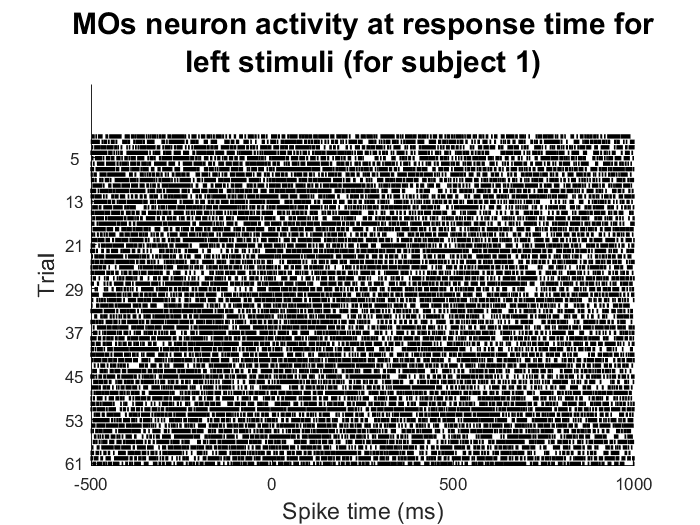

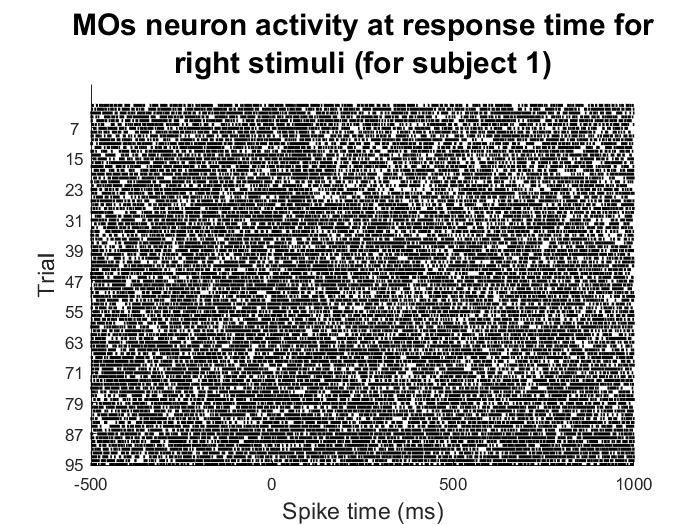

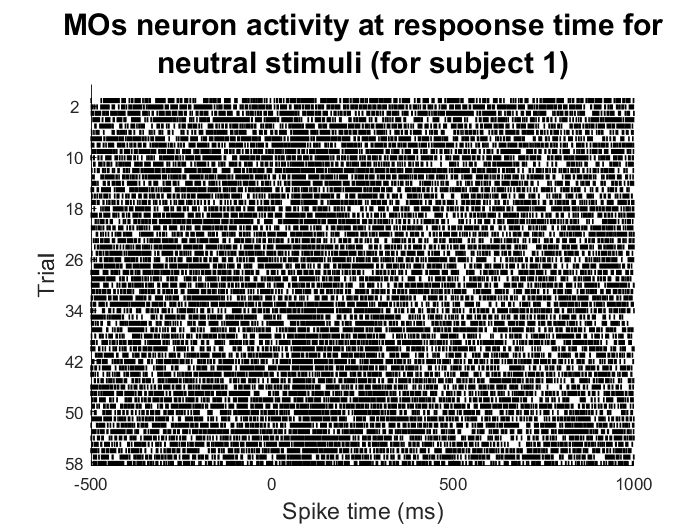

For the neutral stimuli, there is more neural activity at the response time, compared to when there was a clear left or right stimuli.

% motor neuron activity during response to left vs right vs neutral trials
raster_subject1_directional(beh, spikes)

%Erica = 100%

VISp neuron activity during stimulus of high, medium, and no difference between right and left:

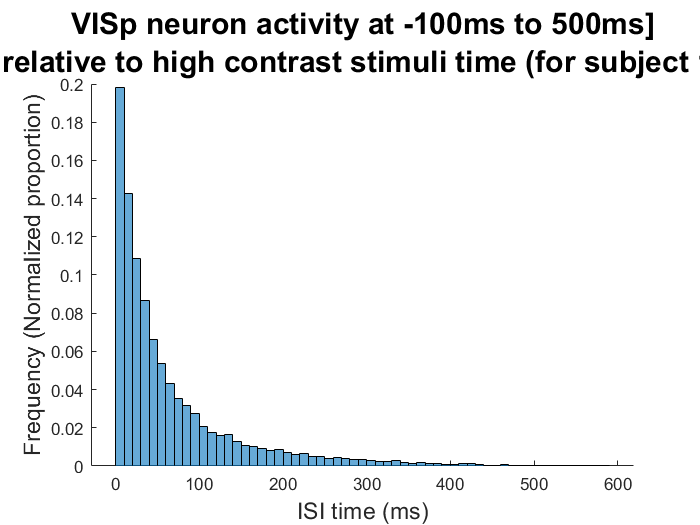

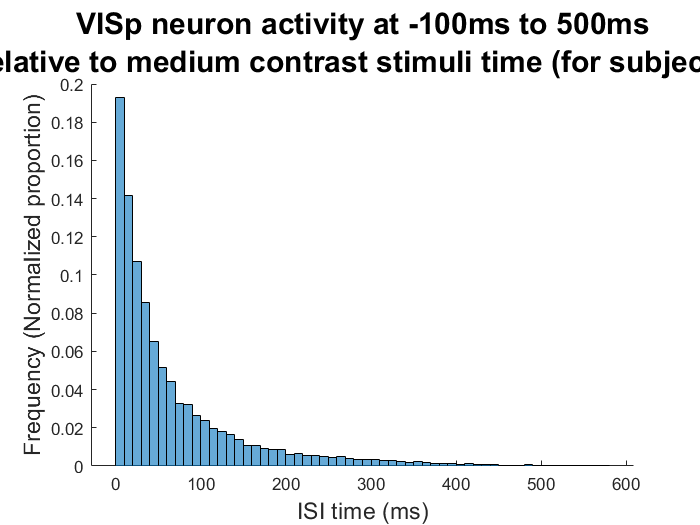

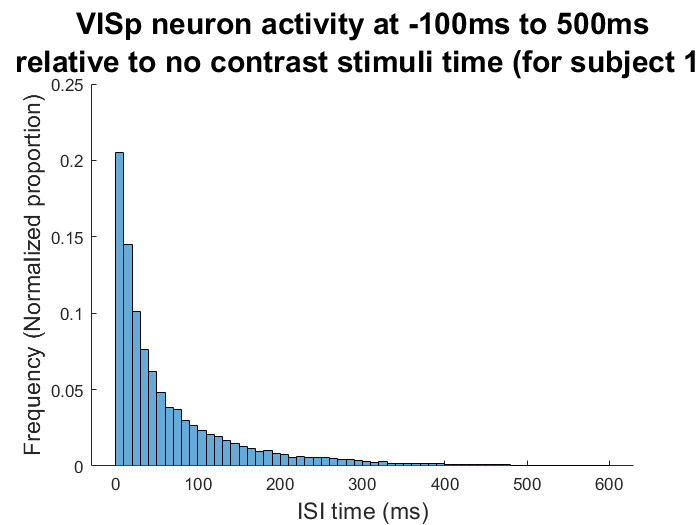

The ISI for high and medium differences between left/right are very similar. When there is no difference between left/right, there are relatively more interspike intervals on the shorter side -- there is more frequent spiking of the visual neuron when there is no difference between left/right.

% visual neuron activity during stimulus of high, medium, and no difference between right and left
isi_subject1_contrast(beh, spikes)

%Erica = 100%

PSTH for average spike counts during stimulus times for motor and and visual neurons. CI's shown by red and yellow edges.

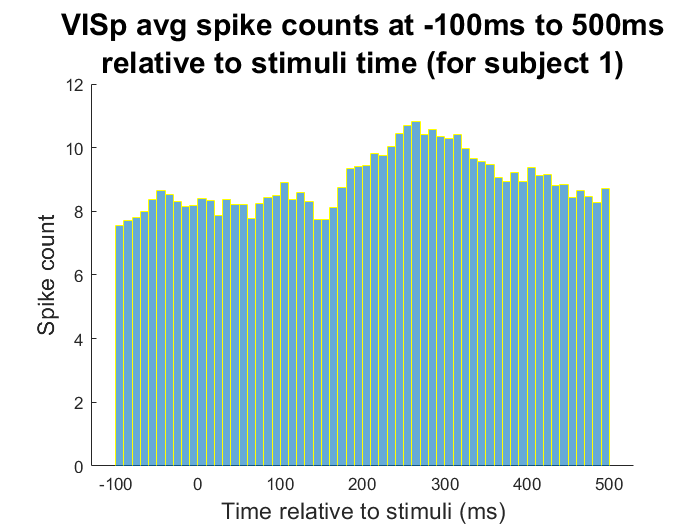

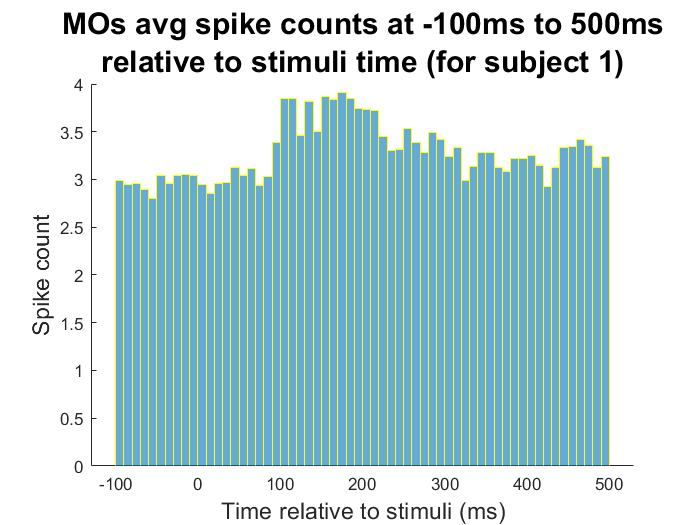

Overall, there is higher spike count for the visual neurons compared to the motor neurons. The motor neurons peak slightly before the visual neurons.

% average spike counts during stimulus times for motor and visual neurons
psth_avg_spike_count(beh, spikes)

%Erica = 80, Paul = 20%

plot gaze position for subject 1 for 500 ms after stimulus apppears

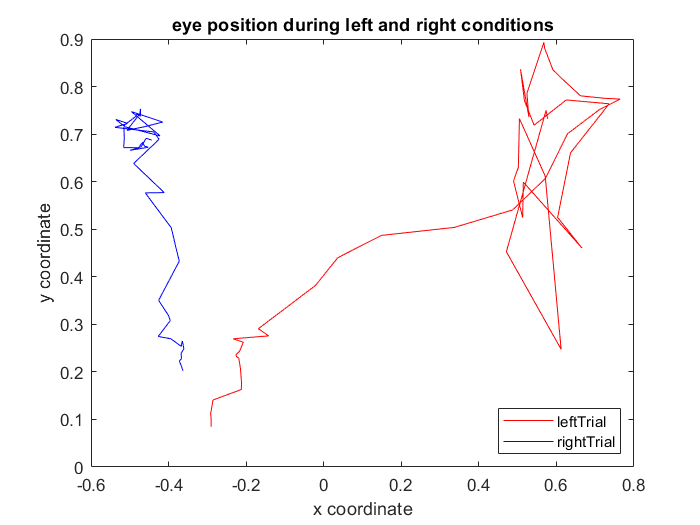

we see that the mouses gaze seems to be drawn toward the side of the screen with the higher contrast stimulus

% visualize gaze after stimulus appears
gaze_tracking() 

%Paul = 100%

show wheel position during the trial from stimulus presentation

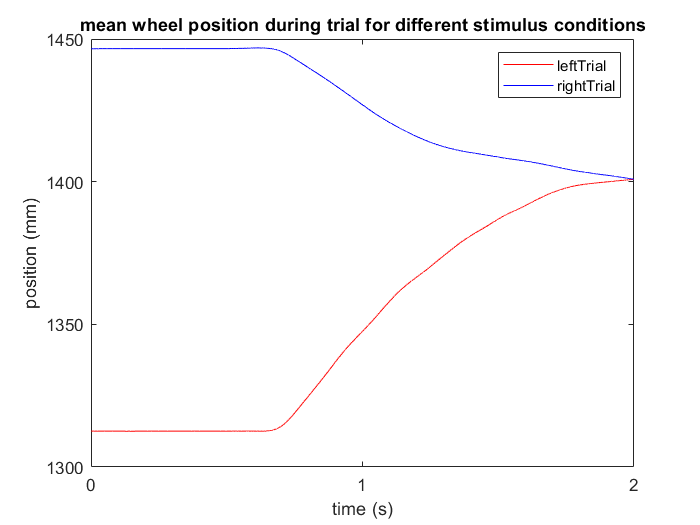

wheel position decreases for rightward responses, and increases for leftward responses, which shows the animal was successfully manipulating the wheel

% visualize wheel position during trial
wheel_position()

%Paul = 100%

plot number of inaccurate responses for each delay time. Error calculated by subtracting real data from SD of means of bootstrapped data, then binning. CIs shown by red and yellow edges.

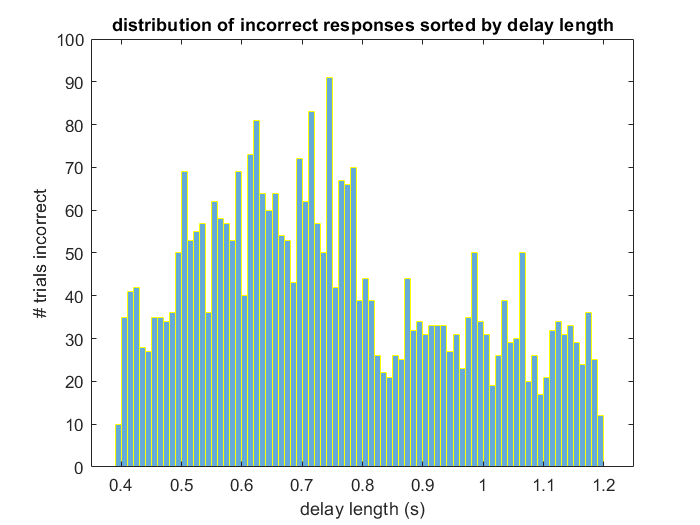

there seems to be less incorrect responses with longer delays

%histogram of accuracy sorted by delay interval
accuracy_v_delay()

%Paul = 100%

## Analysis

% Spike train variability for MOs 50ms 
% before / after 
% stimulus / go cue / response
spike_train_variability(beh, spikes)

Find the Fano Factor of 50 ms before audio go-cue, 50 ms after audio go-cue, 50 ms before visual go-cue, and 50 ms after visual go-cue.MOs Fano Factor for spike count 50 ms before stimulus

ans = 151.8083

p = 1.0022

MOs Fano Factor for spike count 50 ms after stimulus

ans = 154.1373

p = 1.0031

MOs Fano Factor for spike count 50 ms before go cue

ans = 158.5300

p = 1.0003

MOs Fano Factor for spike count 50 ms after go cue

ans = 158.0674

p = 1.0053

MOs Fano Factor for spike count 50 ms before response

ans = 144.1241

p = 0.9972

MOs Fano Factor for spike count 50 ms after response

ans = 154.2192

p = 0.9866

Fano Factor of spike count in MOs is always higher (relatively higher spike count variability)after stimulus / go cue / response than before.
Fano Factor of spike count in MOs is lowest overall after response -- there is relatively lower spike count variability after response.

%Erica = 90% Paul = 10%

% Encoder for response time on MOs spike rates
encoding_response_time(beh, spikes)

Linear regression for response time on MOs spike rate 50 ms before audio go-cue, 50 ms after stimulus 50 ms before visual go-cue, and 50 ms after go-cue 50 ms before response, and 50 ms after response.

model_coeffs = 7×4 table
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         2.4253       0.29272      8.2855    1.4627e-14
    x1             -0.00036449    0.00041212    -0.88442        0.3775
    x2              2.7755e-05    0.00046245    0.060017        0.9522
    x3             -0.00051576    0.00048451     -1.0645       0.28835
    x4              5.5686e-05    0.00042663     0.13052       0.89628
    x5              -0.0013219    0.00046603     -2.8365     0.0050147
    x6             -0.00049991    0.00047654      -1.049       0.29538


model_summary = 3×5 table
                SumSq     DF     MeanSq       F        pValue 
                ______    ___    _______    ______    ________

    Total       82.255    213    0.38617                      
    Model       5.3961      6    0.89935    2.4222    0.027688
    Residual    76.859    207     0.3713                      


The model has quite a low p-value (0.02).The coefficients all have a high p-value, except for that of the spike rate of MOs prior to response (p = 0.005).The coefficient for spike rate prior to response is -0.0013, which tells us that a higher MOs spike rate prior to response corresponds very slightly to a lower response time.

%Erica = 100%

% Classifiers for response speed on MOs spike counts during response
classify_response_speed(beh, spikes)

Classify reaction speeds as fast (< 1 sec) or slow (> 2 sec)


glm_percentage_classified_correctly = 60.15%


lasso_percentage_classified_correctly = 67.05%
svm_percentage_classified_correctly = 66.10%
Classification percentage for all 3 models were quite low, between approximately 60-68

%Erica = 100%

reduce dimensionality and examine what low d state best captures the activity of the neurons in MOs

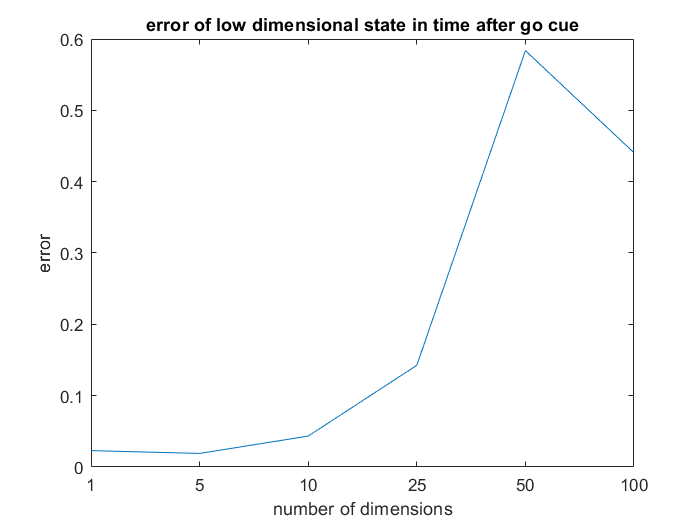

error grows with more dimensions. It may be the secondary motor area isnt very modulated in the time after stimulus presentation

%linearly reduce dimensionality
load('sorted_data/neural/spike_pca.mat');
condSpikeCounts = prepDimReduct(beh,spikes);
dimensionalityReduction(condSpikeCounts);

load('sorted_data/neural/spikes.mat');
%Paul = 100%

%train auto encoder
%%%%%%% WIP %%%%%%%%%
%(Paul's taking point)